# Create and Customize 3-D Contour Plots

3-D contour plots contain the isolines of matrix `Z`, where `Z` contains height values on the *x*-*y* plane

### Create Data

Use meshgrid in a helper function to generate data for a 3-D contour plot with the following relationship: $z=\sin \left(x\right)+\cos \left(y\right)$.

[x,y,z] = createData();

### Basic 3-D Contour Plot

Visualize the function $z=\sin \left(x\right)+\cos \left(y\right)$. The contour color varies by height in the z-direction.

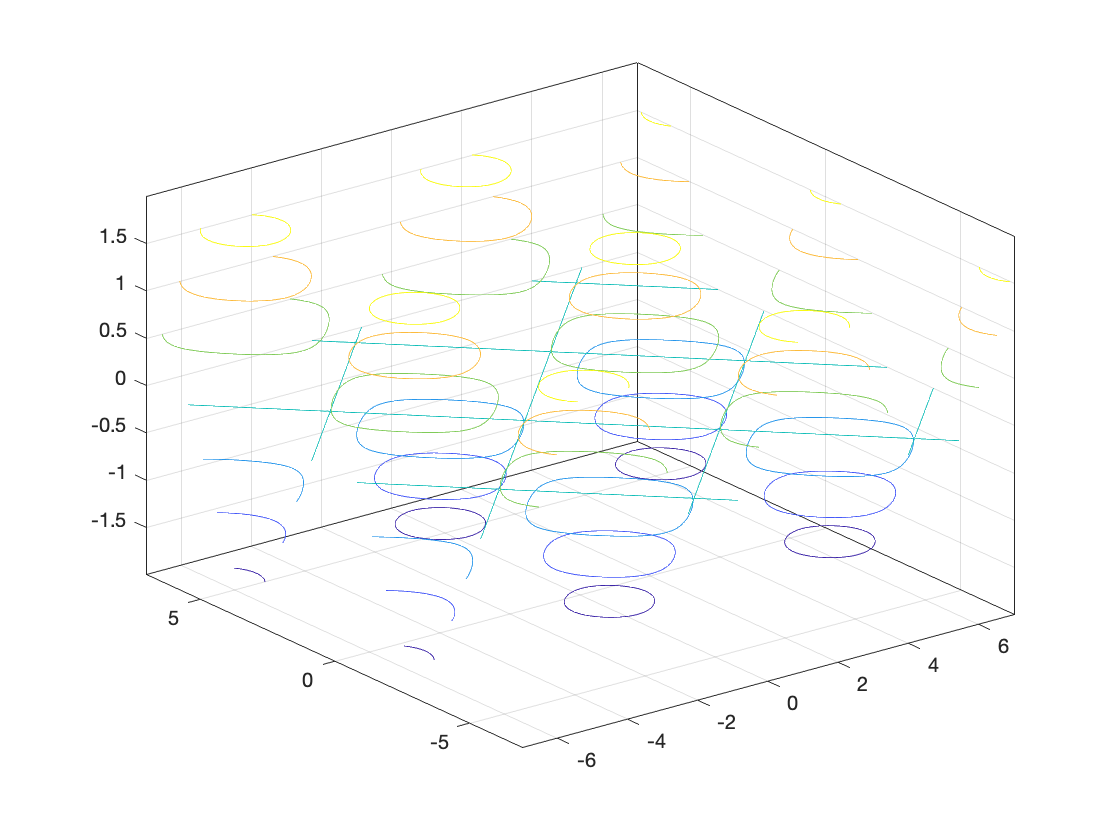

contour3(x,y,z);

## Customization

### Customize Contour Levels and Lines

Specify the number of contour levels as a 2nd argument to `contour3`. This can increase the number of contour lines, and help improve the visualization. Specify the *LineWidth* of the contour lines using a Name, Value pair argument.

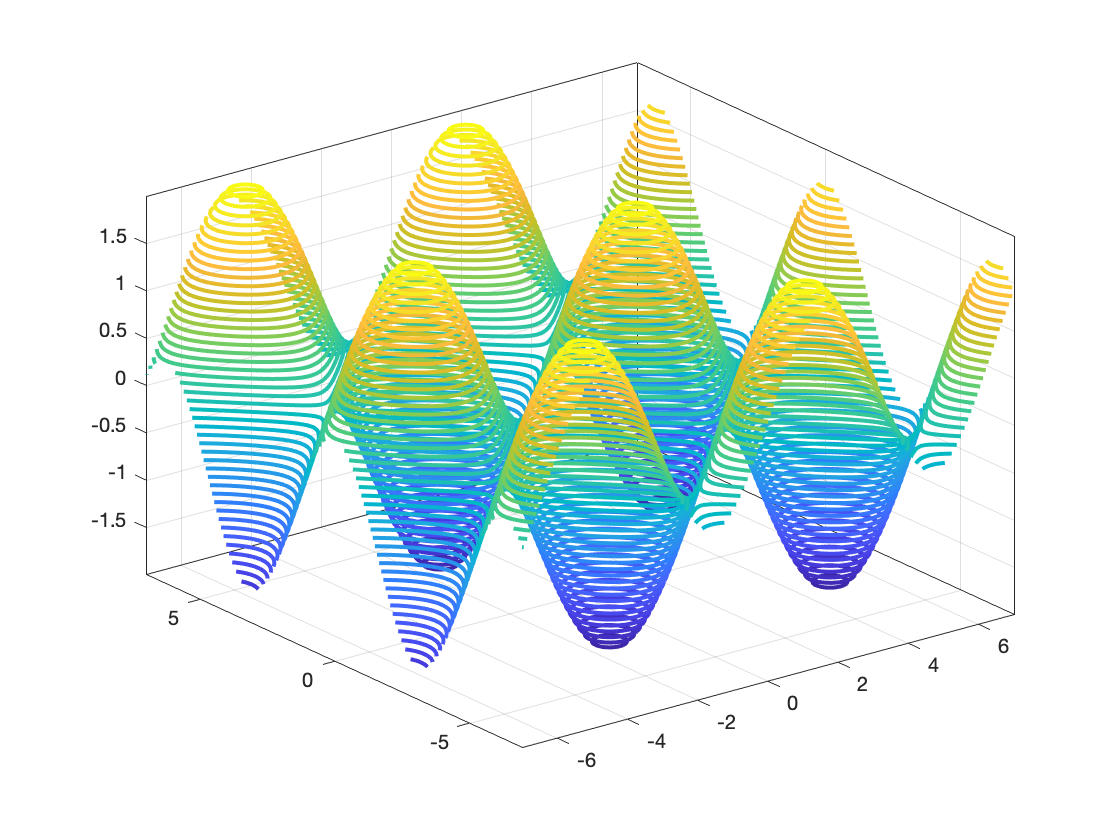

contourLevels = 50; 
LineWidth = 2; 

figure
[~,c] = contour3(x,y,z,...
    contourLevels,...               % Specify a scalar integer number of contour levels
    "LineWidth",LineWidth);         % Specify the contour line width

### Change Chart Colormap and Add Labels

There are several default colormaps specified in MATLAB, some are shown in the drop down menu. Add axes labels and a title to complete the plot.

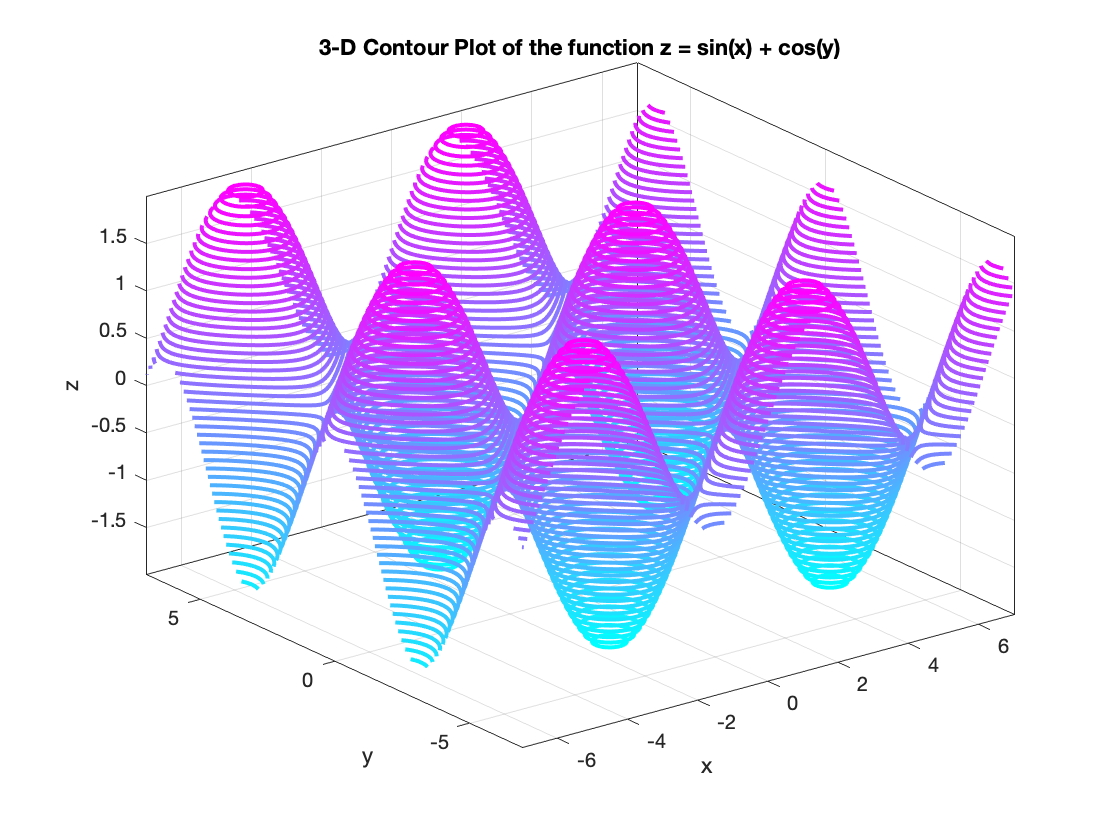

colormap("cool");    % Specify a colormap to use in the contour3 plot       
title("3-D Contour Plot of the function z = sin(x) + cos(y)",...
    "FontWeight","Bold");        % Set title font to bold
xlabel("x");
ylabel("y");
zlabel("z");

## **Additional Information**

### **Get All Contour Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Contour, uncomment the following code. View or modify these properties using dot notation.

% get(c)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[contour3](https://www.mathworks.com/help/matlab/ref/contour3.html)

### Helper Functions

This function generates x,y, and z data with the following relationship: $z=\sin \left(x\right)+\cos \left(y\right)$.

function [x,y,z] = createData()
    [x,y] = meshgrid(-7:0.1:7);
    z = sin(x) + cos(y);
end


Copyright (c) 2021, The MathWorks, Inc.